# Planar dynamical system with two fiexed points

Consider the system governed by the system of ODEs


$$\dot{x} =  x(y-b) \\
\dot{y} = cy(x-a)$$


with the parameters    a,b,c>0    This system has two fixed points: a stable node $\mathbf{x}_0=(0,0)$ and a saddle-type fixed point at $\mathbf{x}_1=(a,b)$. In the following, we take a=b=1 and c = 2.5 and study the heteroclinic orbit connecting $\mathbf{x}_1$to $\mathbf{x}_0$.

The unstable eigenvector of $\mathbf{x}_1$ plays a key role, which is given by $\mathbf{v}_1 = $$\left\lbrack \begin{array}{c}
\frac{\sqrt{\textrm{abc}}}{\textrm{bc}}\\
1
\end{array}\right\rbrack$.

Here we  generate the training trajectory: 

a = 1;
b = 1;
c = 2.5;

odefun = @(t,x) planar(t, x, 1, 1, 2.5);
t_eval = linspace(0, 40, 1000);

unstable_eigenvector = [sqrt(a*b*c)/(b*c), 1.];

eps = 1e-3;
fixedpoint = [a,b];
ic = fixedpoint - eps * unstable_eigenvector;

[t, y] = ode45(odefun, t_eval, ic);


% put into a format usable for SSMLearn

xData = {};
xData{1,1} = t';
xData{1,2} = y;

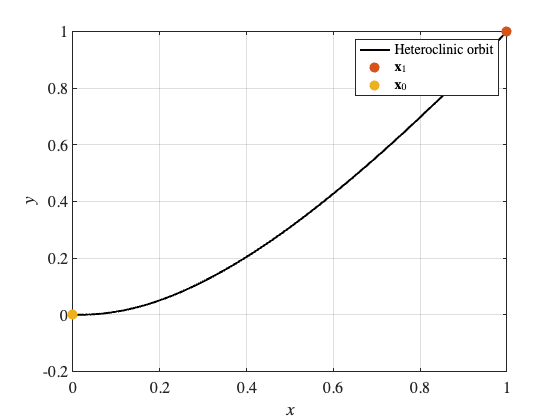

customFigure('latex', true);
plot(y(:,1), y(:,2), 'k-', 'Linewidth', 2, 'Displayname', 'Heteroclinic orbit')
plot(a,b, '.', 'Markersize', 30, 'DisplayName', '$\mathbf{x}_1$')
plot(0,0, '.', 'Markersize', 30, 'DisplayName', '$\mathbf{x}_0$')
xlabel('$x$')
ylabel('$y$')

legend('Interpreter','Latex')

We also generate a few trajectories for testing.

%rng(3); % set seet for reproducability
nTest = 5;
load('TestData.mat');
%perturbations = (rand(nTest,2)-0.5)*6e-2 ;
%IC_test = fixedpoint - 5e-2*unstable_eigenvector + perturbations; % generate ics that are on the left side of x1

tarraytest = linspace(0, 10, 1000);
%testTrajs = [];
for i=1:nTest
    iTraj = 1 + i;
    %[~, x] = ode45(odefun, tarraytest, IC_test(i, :));
    xData{iTraj, 1} = tarraytest;
    xData{iTraj, 2} = squeeze(testtrajs(i,:,:))';
end

indTrain = 1;
nTrain = 1;
indTest = indTrain+1 : nTest + nTrain;



 Visualize all trajectories.

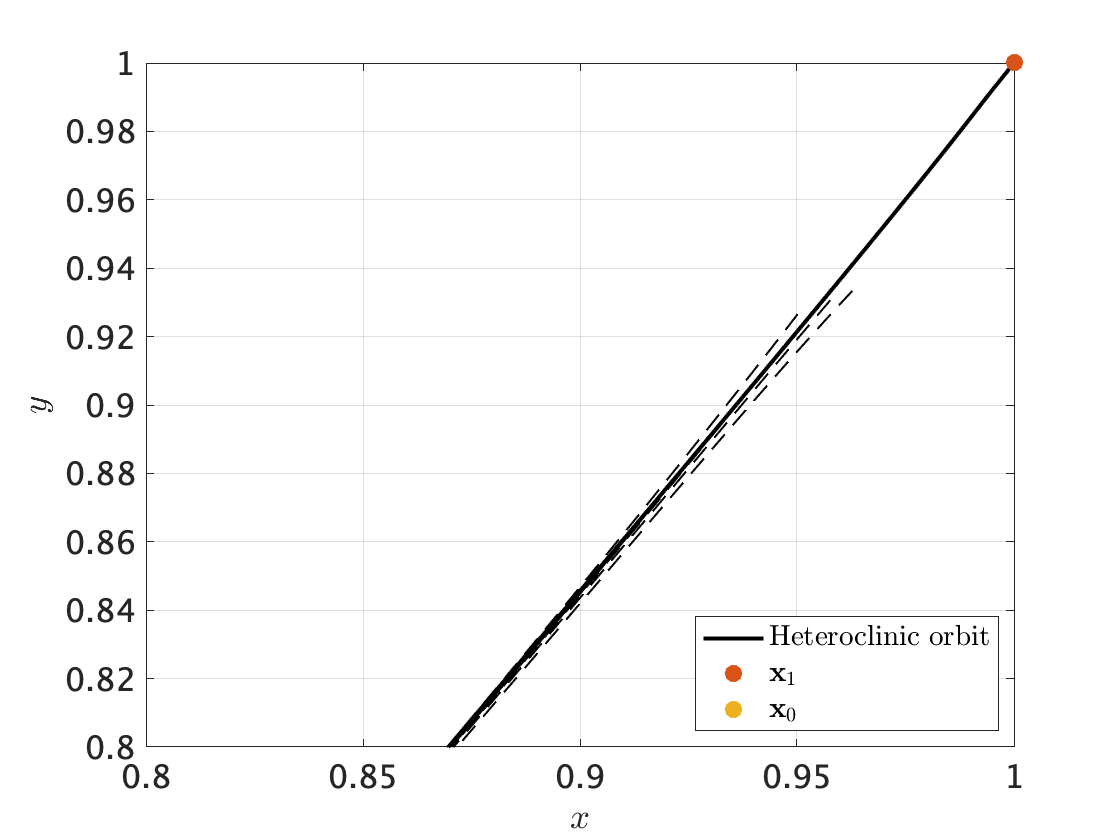

customFigure('latex', true);

plot(xData{indTrain, 2}(:,1), xData{indTrain, 2}(:,2), 'k-', 'Linewidth', 2, 'Displayname', 'Heteroclinic orbit')
plot(a,b, '.', 'Markersize', 30, 'DisplayName', '$\mathbf{x}_1$')
plot(0,0, '.', 'Markersize', 30, 'DisplayName', '$\mathbf{x}_0$')

xlabel('$x$')
ylabel('$y$')
xlim([0.8, 1])
ylim([0.8, 1])

legend('Interpreter','Latex', 'location','SE')
for iTraj=indTest
    plot(xData{iTraj, 2}(:,1), xData{iTraj, 2}(:,2), 'k--', 'Linewidth', 1, 'HandleVisibility','off');
end

## Fitting the reduced dynamics

We select only the first coordinate of the trajectories to be observed and fit a fractional-style reduced order model to their time evolution. 

To this end, we need to precompute the fractional powers. The ratio of eigenvalues of the origin is 


$$\frac{\lambda_2}{\lambda_1}=\frac{c}{a} = 2.5$$


yData = {};
for iTraj = 1:nTest+nTrain
    yData{iTraj,1} = xData{iTraj, 1};
    yData{iTraj,2} = xData{iTraj, 2}(:,1)';
end

polynomialOrder = 5;
spectralRatio = c/a;
powersAll = [];
for i1 = 0:polynomialOrder
    for i2 = 0: polynomialOrder
        power = i1 + i2*spectralRatio;
        if (power <= polynomialOrder) && (i1 + i2)>0
            powersAll = [powersAll; power];
        end
    end
end

RDInfo = IMDynamicsFlowFractional(yData(indTrain,:),'R_PolyOrd', polynomialOrder, 'l_vals',1e-3, 'powers', powersAll);

Estimation of the reduced dynamics...  Done. 


R = RDInfo.reducedDynamics.map;

The returned model reads as 

RDInfo.reducedDynamics.phi

ans = function_handle with value:
    @(u1)[u1.^(5.0./2.0);u1.^5;u1;u1.^(7.0./2.0);u1.^2;u1.^(9.0./2.0);u1.^3;u1.^4;u1.^5]


yRec = integrateFlows(R, yData);


% Plot reconstruction of training trajectories
customFigure('latex', true);
for iTraj = indTrain
    if iTraj == indTrain(1)  % only display legend for one trajectory
        plot(yData{iTraj,1}, yData{iTraj,2}(1,:), 'Color', 'black', 'Linewidth', 2);
        plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'r--','Linewidth',2);
    else
        plot(yData{iTraj,1}, yData{iTraj,2}(1,:), 'Color', 'black', 'Linewidth', 2, 'HandleVisibility','off');
        plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'r--','Linewidth',2, 'HandleVisibility','off');
    end

end

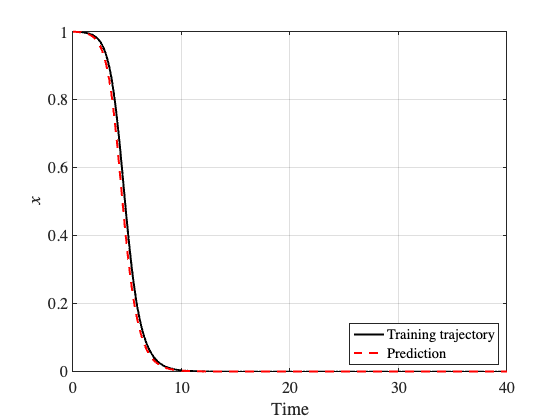

xlabel('Time', 'Interpreter','latex');
ylabel('$x$', 'Interpreter','latex');
legend('Training trajectory','Prediction','location','SE')

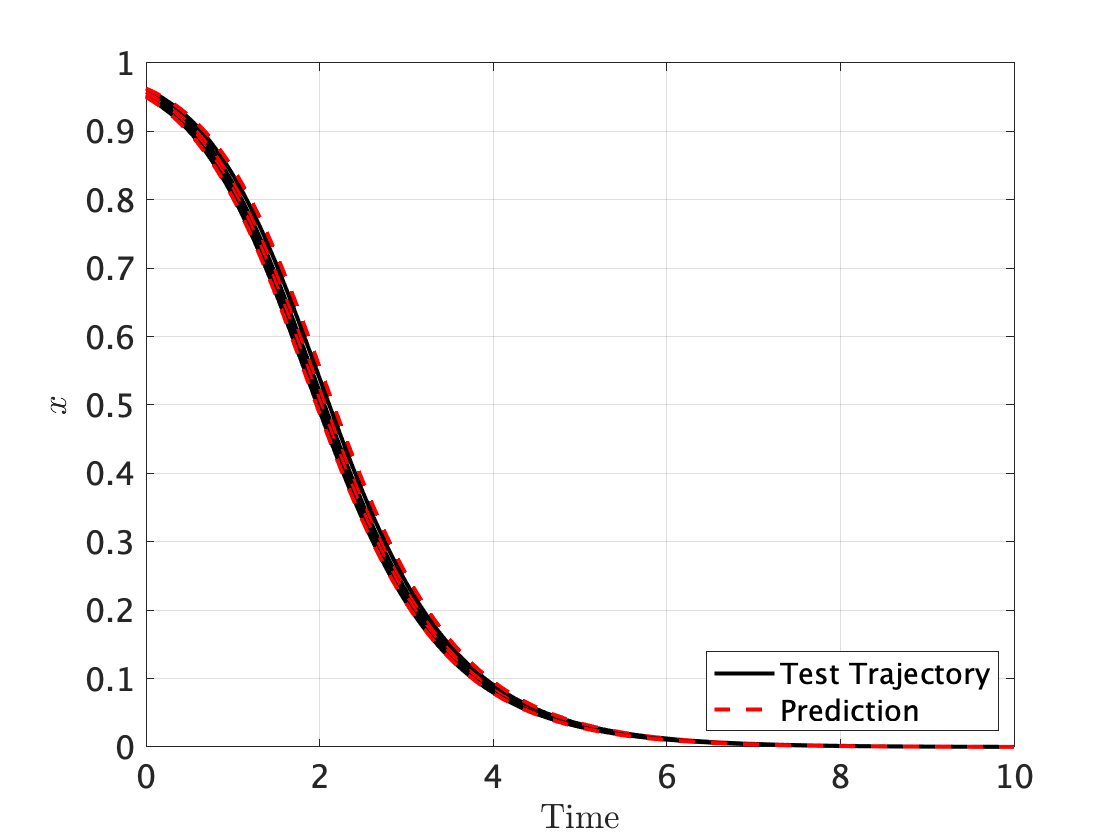

%ylim([-1e-3 1])
%% Plot reconstruction of test trajectories
customFigure('latex', true);
for iTraj = indTest
    if iTraj == indTest(1)  % only display legend for one trajectory
        plot(yData{iTraj,1},yData{iTraj,2}(1,:), 'Color', 'black', 'Linewidth',2,'Displayname','Test Trajectory')
        plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'--', 'Color', 'Red', 'Linewidth',2,'Displayname','Prediction')
    else
        plot(yData{iTraj,1},yData{iTraj,2}(1,:),'k-','Linewidth',2, 'HandleVisibility','off')
        plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'r--','Linewidth',2, 'HandleVisibility','off')
    end
end
legend('location','SE')
xlabel('Time', 'Interpreter','latex');
ylabel('$x$', 'Interpreter','latex');

%xlim([iniTime 700])


## In comparison, the integer-powered model 

RDInfoInt = IMDynamicsFlowFractional(yData(indTrain,:),'R_PolyOrd', polynomialOrder, 'l_vals',1e-3);

Estimation of the reduced dynamics...  Done. 


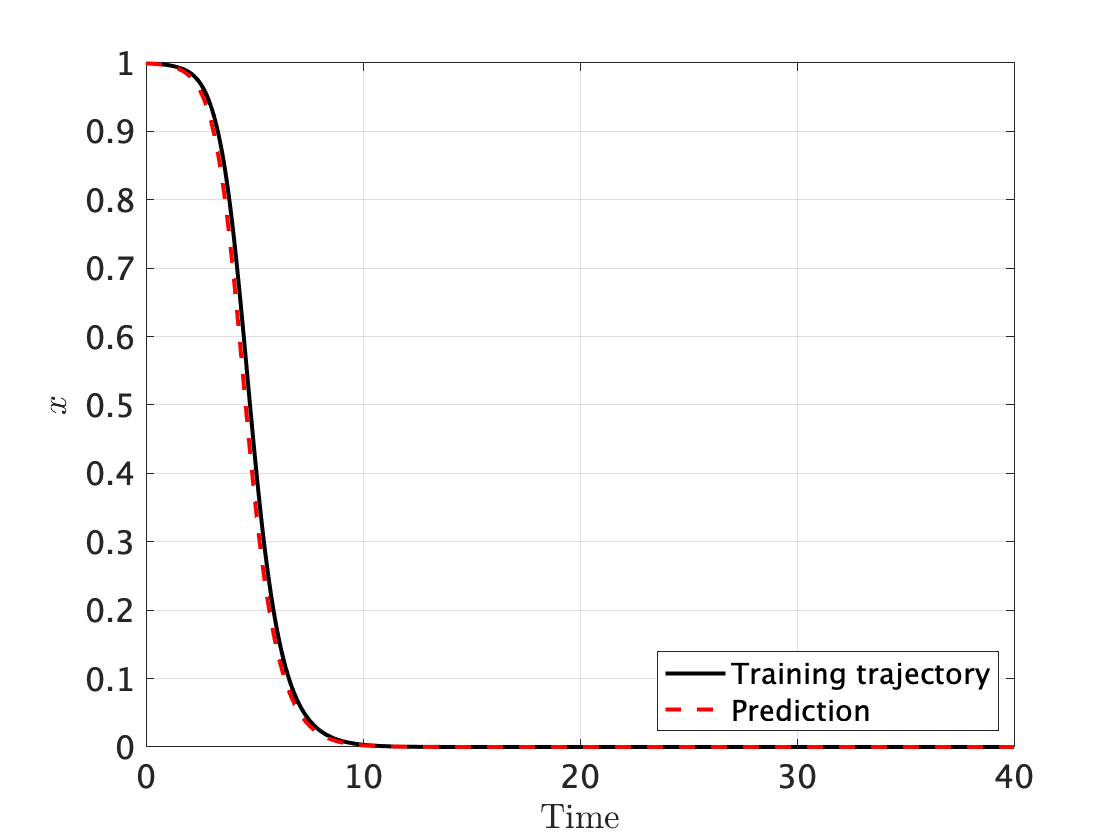

Rint = RDInfoInt.reducedDynamics.map;
yRecInt = integrateFlows(Rint, yData);


% Plot reconstruction of training trajectories
customFigure('latex', true);
for iTraj = indTrain
    if iTraj == indTrain(1)  % only display legend for one trajectory
        plot(yData{iTraj,1}, yData{iTraj,2}(1,:), 'Color', 'black', 'Linewidth', 2);
        plot(yRecInt{iTraj,1},yRecInt{iTraj,2}(1,:),'r--','Linewidth',2);
    else
        plot(yData{iTraj,1}, yData{iTraj,2}(1,:), 'Color', 'black', 'Linewidth', 2, 'HandleVisibility','off');
        plot(yRecInt{iTraj,1},yRecInt{iTraj,2}(1,:),'r--','Linewidth',2, 'HandleVisibility','off');
    end

end
xlabel('Time', 'Interpreter','latex');
ylabel('$x$', 'Interpreter','latex');
legend('Training trajectory','Prediction','location','SE')

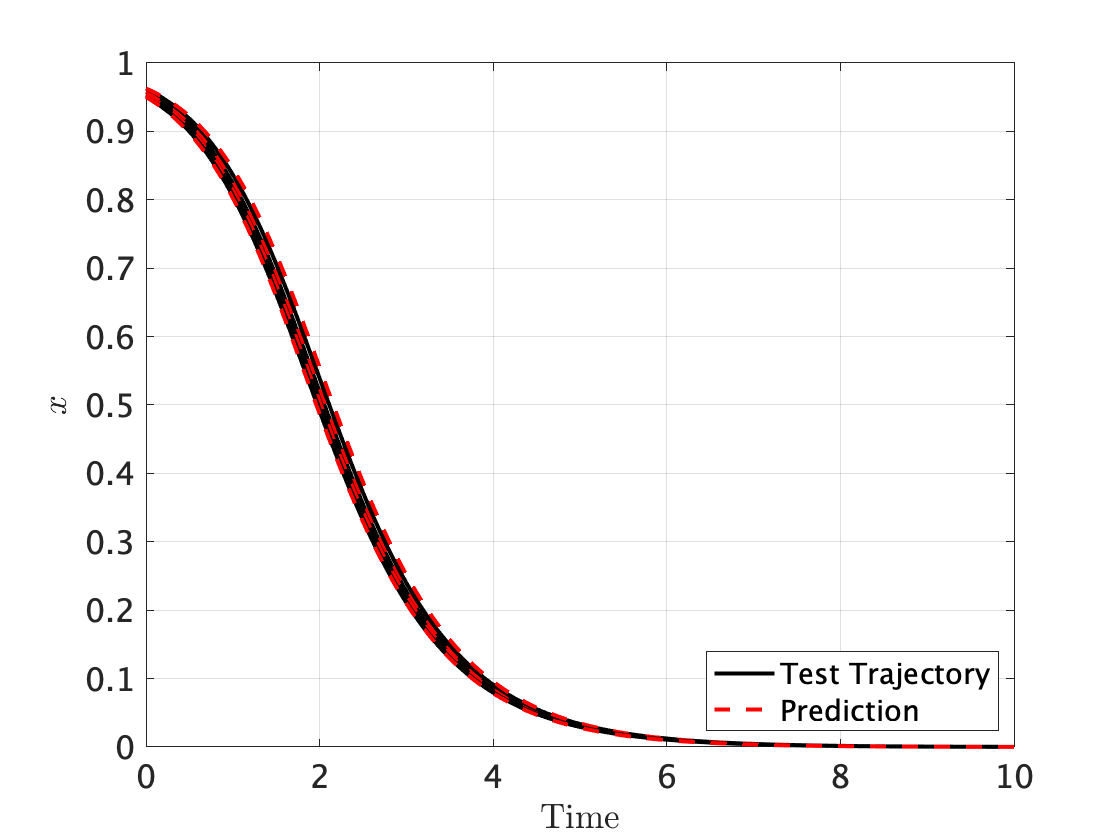

%ylim([-1e-3 1])
%% Plot reconstruction of test trajectories
customFigure('latex', true);
for iTraj = indTest
    if iTraj == indTest(1)  % only display legend for one trajectory
        plot(yData{iTraj,1},yData{iTraj,2}(1,:), 'Color', 'black', 'Linewidth',2,'Displayname','Test Trajectory')
        plot(yRecInt{iTraj,1},yRecInt{iTraj,2}(1,:),'--', 'Color', 'Red', 'Linewidth',2,'Displayname','Prediction')
    else
        plot(yData{iTraj,1},yData{iTraj,2}(1,:),'k-','Linewidth',2, 'HandleVisibility','off')
        plot(yRecInt{iTraj,1},yRecInt{iTraj,2}(1,:),'r--','Linewidth',2, 'HandleVisibility','off')
    end
end
legend('location','SE')
xlabel('Time', 'Interpreter','latex');
ylabel('$x$', 'Interpreter','latex');

%xlim([iniTime 700])

Compare the errors of each model.

errors = [];
for iTraj = indTest
    errors = [errors; abs(yData{iTraj,2} - yRec{iTraj,2})/max(yData{iTraj, 2})];
end
avgError = mean(errors);


errorsInt = [];
for iTraj = indTest
    errorsInt = [errorsInt; abs(yData{iTraj,2} - yRecInt{iTraj,2})/max(yData{iTraj, 2})];
end
avgErrorInt = mean(errorsInt);

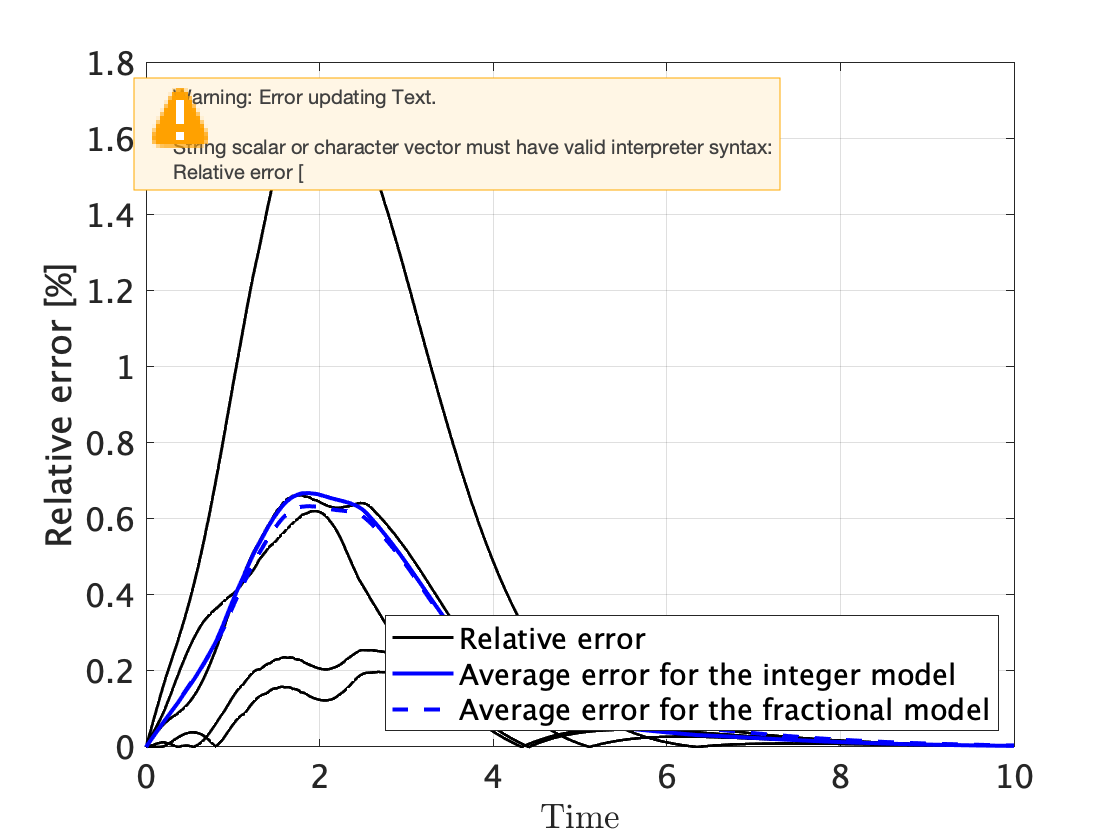

customFigure('latex', true);

for iTraj = indTest
    if iTraj == indTest(1)  % only display legend for one trajectory
        semilogy(yData{iTraj,1}, errors(iTraj-1,:)*100, 'Color', 'black', 'Linewidth',1.5,'Displayname','Relative error')
    else
        semilogy(yData{iTraj,1}, errors(iTraj-1,:)*100, 'Color', 'black', 'Linewidth',1.5,'HandleVisibility','off')
    end
end
semilogy(yData{iTraj,1}, avgError*100, '-', 'Color', 'blue', 'linewidth', 2., 'Displayname', 'Average error for the integer model');
semilogy(yData{iTraj,1}, avgErrorInt*100, '--', 'Color', 'blue', 'linewidth', 2., 'Displayname', 'Average error for the fractional model');


legend('location','SE')
xlabel('Time', 'Interpreter','latex');
ylabel('Relative error [%]', 'Interpreter','latex');